## Classification of MNIST Digits

clear

### Load the Training Data

Download the MNIST Data [here](https://lucidar.me/en/matlab/load-mnist-database-of-handwritten-digits-in-matlab/). Load the data set in the workspace.

data = load("mnist.mat");
yTrain = categorical(data.training.labels);
yTest = categorical(data.test.labels);

xTrain = reshape(data.training.images,28,28,1,numel(yTrain));
xTest = reshape(data.test.images,28,28,1,numel(yTest));

trainDs = augmentedImageDatastore([28 28],xTrain,yTrain,"ColorPreprocessing","gray2rgb");
testDs = augmentedImageDatastore([28 28],xTest,yTest,"ColorPreprocessing","gray2rgb");

### Setting the Training Parameters

To train our network, we are going to use a convolutional neural network (CNN).

First, let's set up the layers.

% layers=[imageInputLayer([28 28 3],'Name','input')
%     convolution2dLayer(3,6,'Padding','same')
%     reluLayer
%     batchNormalizationLayer
%     maxPooling2dLayer(2,'Stride',2)
%     convolution2dLayer(3,16)
%     reluLayer
%     batchNormalizationLayer
%     maxPooling2dLayer(2,'Stride',2)
%     fullyConnectedLayer(120,'name','f1')
%     reluLayer
%     fullyConnectedLayer(84,'name','f2')
%     reluLayer
%     fullyConnectedLayer(10,'name','f3')
%     softmaxLayer
%     classificationLayer];

layers = [
    imageInputLayer([28 28 3],"Name","imageinput")
    convolution2dLayer([3 3],32,"Name","conv","Padding","same")
    reluLayer("Name","relu")
    batchNormalizationLayer("Name","batchnorm")
    maxPooling2dLayer([5 5],"Name","maxpool","Padding","same")
    fullyConnectedLayer(128,"Name","fc")
    reluLayer("Name","relu_1")
    fullyConnectedLayer(64,"Name","fc_1")
    reluLayer("Name","relu_2")
    fullyConnectedLayer(10,"Name","fc_2")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

Then, we set the training options.

% options = trainingOptions('adam','MaxEpochs',25,...
%     'LearnRateSchedule' ,'piecewise',...
%     'LearnRateDropPeriod',15,'LearnRateDropFactor' ,0.1);

opts = trainingOptions("adam",...
    "MaxEpochs",3,...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",0.001,...
    "Shuffle","every-epoch",...
    "Plots","training-progress");

### Training the Data

Now, we train the network using the [trainNetwork](https://www.mathworks.com/help/deeplearning/ref/trainnetwork.html) command.

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:05 |       15.62% |       3.3940 |          0.0010 |
|       1 |          50 |       00:00:11 |       85.94% |       0.5603 |          0.0010 |
|       1 |         100 |       00:00:15 |       89.84% |       0.3511 |          0.0010 |
|       1 |         150 |       00:00:20 |       90.62% |       0.3103 |          0.0010 |
|       1 |         200 |       00:00:24 |       96.09% |       0.0792 |          0.0010 |
|       1 |         250 |       00:00:29 |       95.31% |       0.1136 |          0.0010 |
|       1 |         300 |  

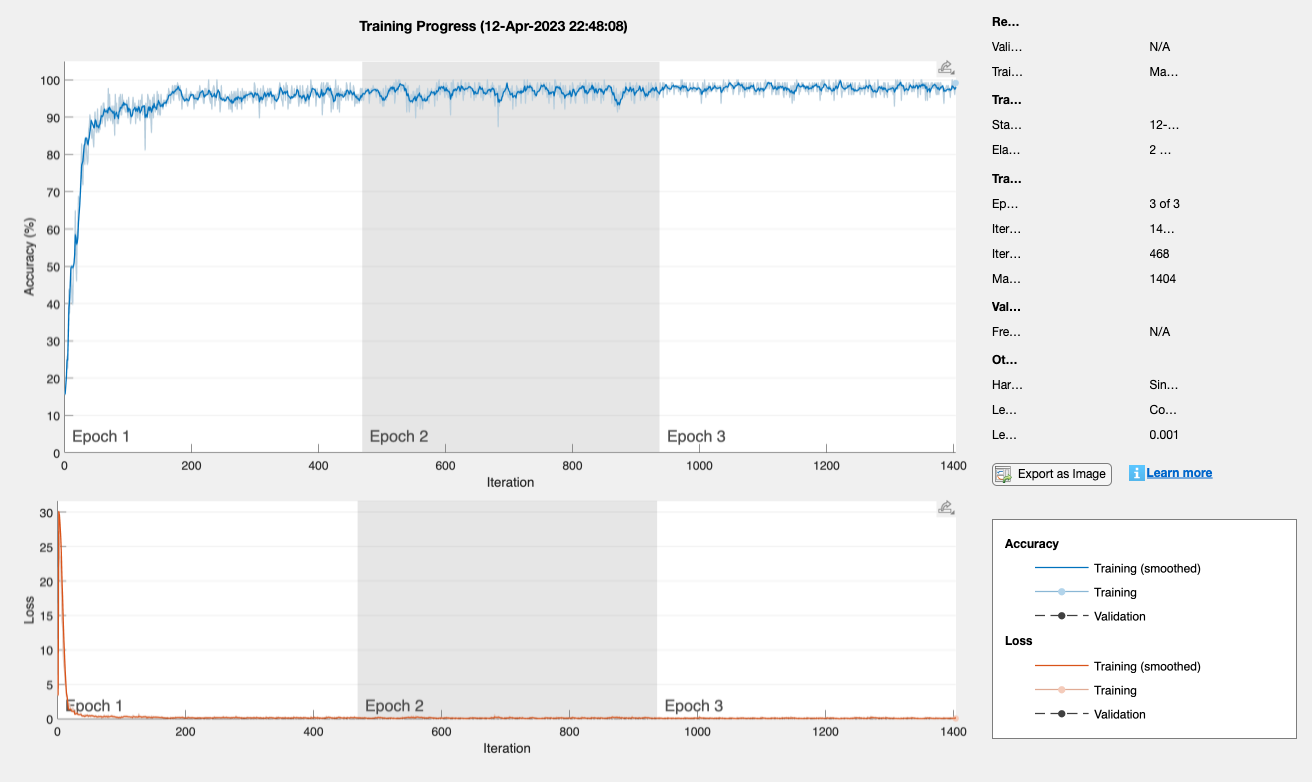

% net = trainNetwork(trainDs,layers,options);

[net, traininfo] = trainNetwork(trainDs,layers,opts);

analyzeNetwork(net)

layer = 2;
name = net.Layers(layer).Name

name = 'conv'

channels = 1:32;
I = deepDreamImage(net,name,channels, ...
    'PyramidLevels',1);

|==============================================|
|  Iteration  |  Activation  |  Pyramid Level  |
|             |   Strength   |                 |
|==============================================|
|           1 |         0.01 |               1 |
|           2 |         0.79 |               1 |
|           3 |         1.60 |               1 |
|           4 |         2.41 |               1 |
|           5 |         3.22 |               1 |
|           6 |         4.03 |               1 |
|           7 |         4.84 |               1 |
|           8 |         5.65 |               1 |
|           9 |         6.46 |               1 |
|          10 |         7.27 |               1 |
|==============================================|
Training finished: Max epochs completed.


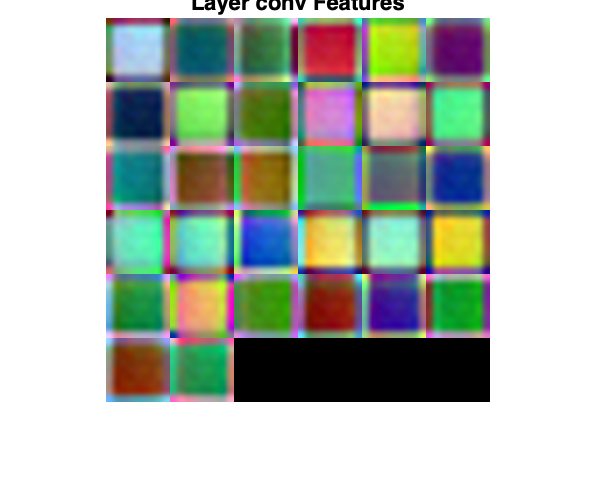

figure
I = imtile(I,'ThumbnailSize',[64 64]);
imshow(I)
title(['Layer ',name,' Features'],'Interpreter','none')

### Evaulating the Performance

testpreds = classify(net,testDs);
nnz(testpreds == yTest)/numel(testpreds)

ans = 0.9759

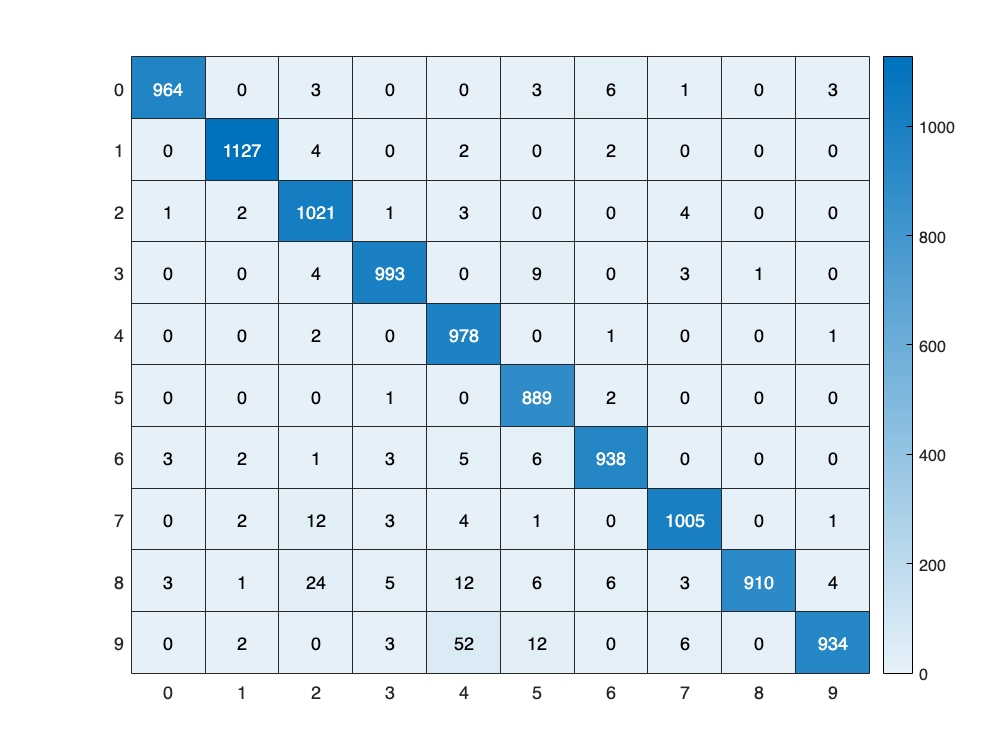

[conf,names] = confusionmat(yTest,testpreds);
heatmap(names,names,conf);